clc
clear
trainingData = readmatrix("../TrainingData/neodata/fault_all_noise_67.csv");
trainingLabel = trainingData(:,12);
trainingData = trainingData(:,1:11);
% load("trainingDataReduced.mat")

validationData = readmatrix("../ValidationData/neodata/fault_all_noise_67.csv");
validationLabel = validationData(:,12);
validationData = validationData(:,1:11);


t = templateSVM('KernelFunction','rbf','KernelScale', 1/(2*0.01),'BoxConstraint',1000);
% t = templateSVM('KernelFunction','rbf');

tic
% SVMModel = fitcecoc(trainingData,trainingLabel,"Learners",t,'OptimizeHyperparameters','auto','HyperparameterOptimizationOptions',struct('AcquisitionFunctionName','expected-improvement-plus'));
SVMModel = fitcecoc(trainingData,trainingLabel,"Learners",t,"Coding","onevsone");
toc

Elapsed time is 24.132343 seconds.


% 

tic
predictedLabel = predict(SVMModel, trainingData);
toc

Elapsed time is 6.576492 seconds.


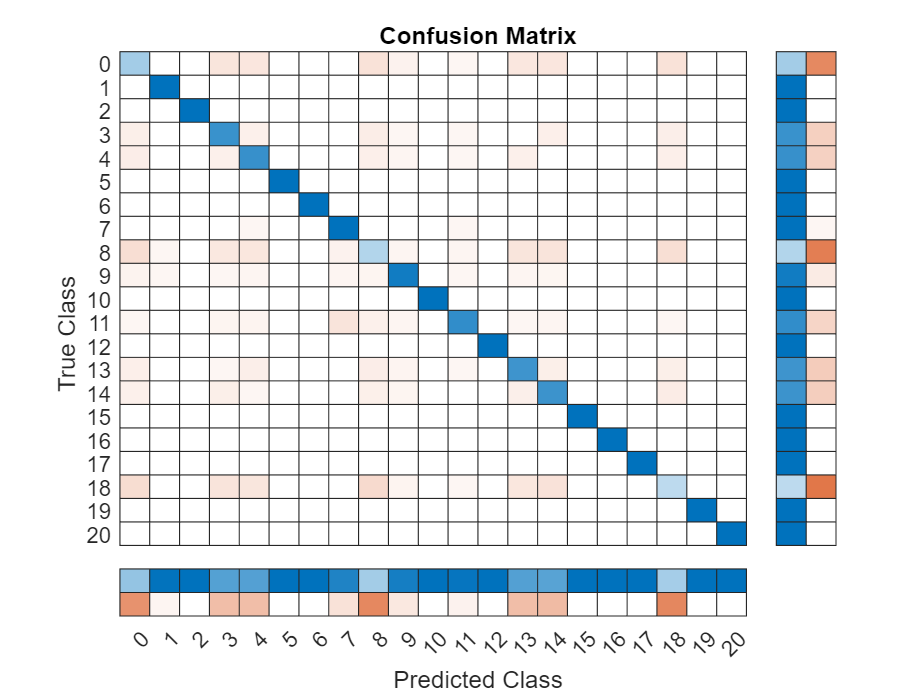


cm = confusionchart(trainingLabel, predictedLabel);
cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';
cm.Title = 'Confusion Matrix';

Correct = predictedLabel == trainingLabel;
Accuracy = mean(Correct)

Accuracy = 0.8367

tic
predictedLabelVal = predict(SVMModel, validationData);
toc

Elapsed time is 0.522193 seconds.


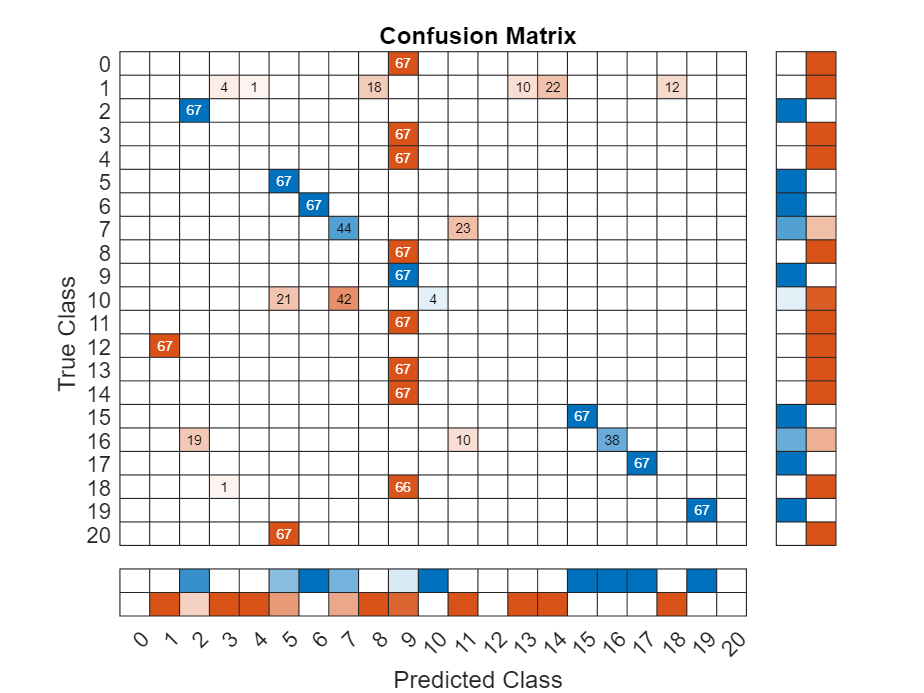

cm = confusionchart(validationLabel, predictedLabelVal);
cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';
cm.Title = 'Confusion Matrix';

Correct = predictedLabelVal== validationLabel;
Accuracy = mean(Correct)

Accuracy = 	1.0e+-3 *

         0         0         0         0         0         0         0         0         0         0    0.7107


function [W mu] = LDA_reduce(D, train, trainLabel, Nk)
    % Calculate mean of each class
    for i=1:21
        mu(i,:)= mean(train(trainLabel == i,:));
    end
    % Calculate total mean
    mu(22,:) = mean(train);

    % Calculate within-class scattesr
    Sw = 0;
    for j=1:size(mu,1)-1
        Sw = Sw + (train(find(trainLabel==j),:)' - mu(j,:)') * (train(find(trainLabel==j),:)' - mu(j,:)')';
    end
    % Calculate between-class scatter
    Sb = Nk .* (mu(1:21,:)' - mu(22,:)') * (mu(1:21,:)' - mu(22,:)')';

    % Use the eigenvalue decomposition and sort it in decending order
    [V e] = eig(Sb,Sw);
    [B,I] = sort(diag(e),'descend');

    % Take D number of eigenvectores corresponding to the largest values
    for i=1:D
        W(:,i) = V(:,I(i));
    end
end
% Reduces the data to the given dimension of W
function newData = reduceData(data, W)
    data = double(data);
    newData = data * W;
end